% Punto 1: Diseño de Ecualizador Analógico (Butterworth)

% 1.Frecuencias Centrales (Hz)
f0 = [102.4, 512, 2560, 12800];

% 2. Frecuencias de Corte (Medias Geométricas)  
fc_1_2 = sqrt(f0(1) * f0(2));   
fc_2_3 = sqrt(f0(2) * f0(3));   
fc_3_4 = sqrt(f0(3) * f0(4));   

% 3. Especificaciones de Atenuación 
Rp = 3;   % Ripple en banda de paso (dB) 
As = 15;  % Atenuación en banda de rechazo (dB) 

% Conversión a Radianes/segundo 
w0 = 2 * pi * f0;
wc_1_2 = 2 * pi * fc_1_2;
wc_2_3 = 2 * pi * fc_2_3;
wc_3_4 = 2 * pi * fc_3_4;

% 4. Cálculo de Órdenes (buttord analógico)
% Filtro 1: Pasabajos
% Pasa hasta fc_1_2, Rechaza desde f0(2) (centro del vecino)
Wp1 = wc_1_2;
Ws1 = w0(2); 
[n1, wn1] = buttord(Wp1, Ws1, Rp, As, 's');

% Filtro 2: Pasabanda
% Pasa entre fc_1_2 y fc_2_3
% Rechaza abajo de f0(1) y arriba de f0(3)
Wp2 = [wc_1_2, wc_2_3];
Ws2 = [w0(1), w0(3)];
[n2, wn2] = buttord(Wp2, Ws2, Rp, As, 's');

% Filtro 3: Pasabanda
% Pasa entre fc_2_3 y fc_3_4
% Rechaza abajo de f0(2) y arriba de f0(4)
Wp3 = [wc_2_3, wc_3_4];
Ws3 = [w0(2), w0(4)];
[n3, wn3] = buttord(Wp3, Ws3, Rp, As, 's');

% Filtro 4: Pasaaltos
% Pasa desde fc_3_4, Rechaza desde f0(3) hacia abajo
Wp4 = wc_3_4;
Ws4 = w0(3);
[n4, wn4] = buttord(Wp4, Ws4, Rp, As, 's');

% 5. Selección del Orden Máximo
N_final = max([n1, n2, n3, n4])

N_final = 3


% 6. Diseño de los Filtros (Butterworth)

% Filtro 1 (LowPass)
[b1, a1] = butter(N_final, wc_1_2, 'low', 's');

% Filtro 2 (BandPass)
[b2, a2] = butter(N_final, [wc_1_2, wc_2_3], 's');

% Filtro 3 (BandPass)
[b3, a3] = butter(N_final, [wc_2_3, wc_3_4], 's');

% Filtro 4 (HighPass)
[b4, a4] = butter(N_final, wc_3_4, 'high', 's');

## Gráficas

% 7. Visualización (Bode)
w_range = logspace(log10(10*2*pi),log10(100000*2*pi),10000); % De 10Hz a 100kHz

h1 = freqs(b1, a1, w_range);
h2 = freqs(b2, a2, w_range);
h3 = freqs(b3, a3, w_range);
h4 = freqs(b4, a4, w_range);

**Bode Filtro 1 (LowPass)**

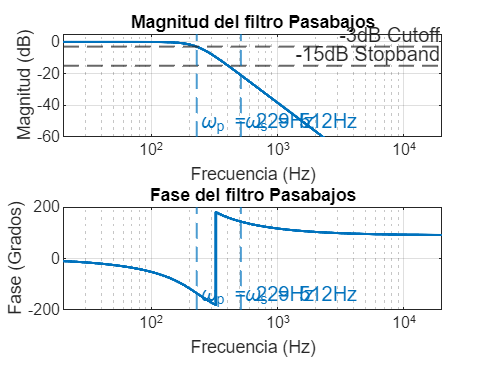

figure(1)
subplot(2,1,1);
semilogx(w_range/(2*pi), 20*log10(abs(h1)), 'LineWidth', 1.5);
grid on;
title('Magnitud del filtro Pasabajos');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud (dB)');

label_3 = '-3dB Cutoff';
label_15 = '-15dB Stopband';

ylim([-60 5]); % Limitar eje Y para ver bien la banda de paso
yline(-3, '--', label_3, 'LineWidth',1,'LabelOrientation','horizontal','HandleVisibility','off'); % Línea de referencia
yline(-15, '--',label_15, 'LineWidth',1,'LabelOrientation','horizontal','HandleVisibility','off'); % Línea de referencia
%xline(fc_1_2, 'Color', [0 0.4470 0.7410], 'LineWidth', 1,'HandleVisibility', 'off');
label1 = sprintf("\\omega_p = %.0f{Hz}", fc_1_2);
label2 = sprintf("\\omega_s = %.0f{Hz}", f0(2));
xline(fc_1_2, '--', label1, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(f0(2), '--', label2, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xlim([20 20000]);

subplot(2, 1, 2);
semilogx(w_range/(2*pi), rad2deg(angle(h1)), 'LineWidth', 1.5);
grid on;
title('Fase del filtro Pasabajos');
xlabel('Frecuencia (Hz)');
ylabel('Fase (Grados)');

%xline(fc_1_2, 'Color', [0 0.4470 0.7410], 'LineWidth', 1,'HandleVisibility', 'off');
xline(fc_1_2, '--', label1, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(f0(2), '--', label2, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xlim([20 20000]);

**Bode Filtro 2 (BandPass)**

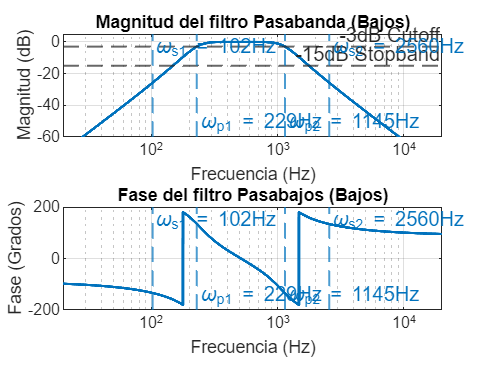

figure(2)
subplot(2,1,1);
semilogx(w_range/(2*pi), 20*log10(abs(h2)), 'LineWidth', 1.5);
grid on;
title('Magnitud del filtro Pasabanda (Bajos)');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud (dB)');


ylim([-60 5]); % Limitar eje Y para ver bien la banda de paso
yline(-3, '--', label_3, 'LineWidth',1,'LabelOrientation','horizontal','HandleVisibility','off'); % Línea de referencia
yline(-15, '--',label_15, 'LineWidth',1,'LabelOrientation','horizontal','HandleVisibility','off'); % Línea de referencia
%xline(fc_1_2, 'Color', [0 0.4470 0.7410], 'LineWidth', 1,'HandleVisibility', 'off');
label3 = sprintf("\\omega_{p1} = %.0f{Hz}", fc_1_2);
label4 = sprintf("\\omega_{p2} = %.0f{Hz}", fc_2_3);
label5 = sprintf("\\omega_{s1} = %.0f{Hz}", f0(1));
label6 = sprintf("\\omega_{s2} = %.0f{Hz}", f0(3));
xline(fc_1_2, '--', label3, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(fc_2_3, '--', label4, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(f0(1), '--', label5, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xline(f0(3), '--', label6, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xlim([20 20000]);

subplot(2, 1, 2);
semilogx(w_range/(2*pi), rad2deg(angle(h2)), 'LineWidth', 1.5);
grid on;
title('Fase del filtro Pasabajos (Bajos)');
xlabel('Frecuencia (Hz)');
ylabel('Fase (Grados)');

xline(fc_1_2, '--', label3, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(fc_2_3, '--', label4, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(f0(1), '--', label5, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xline(f0(3), '--', label6, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xlim([20 20000]);

**Bode Filtro 3 (BandPass)**

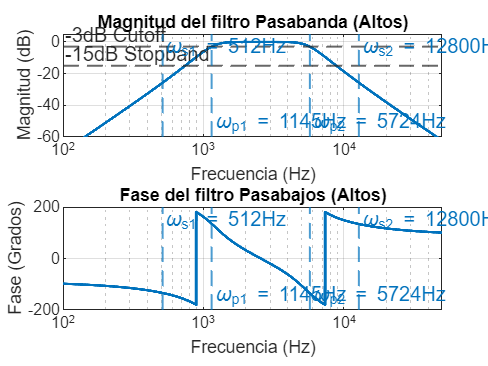

figure(3)
subplot(2,1,1);
semilogx(w_range/(2*pi), 20*log10(abs(h3)), 'LineWidth', 1.5);

grid on;
title('Magnitud del filtro Pasabanda (Altos)');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud (dB)');

ylim([-60 5]); % Limitar eje Y para ver bien la banda de paso
yline(-3, '--', label_3, 'LineWidth',1,'LabelOrientation','horizontal','LabelHorizontalAlignment','left','HandleVisibility','off'); % Línea de referencia
yline(-15, '--',label_15, 'LineWidth',1,'LabelOrientation','horizontal','LabelHorizontalAlignment','left','HandleVisibility','off'); % Línea de referencia
%xline(fc_1_2, 'Color', [0 0.4470 0.7410], 'LineWidth', 1,'HandleVisibility', 'off');
label7 = sprintf("\\omega_{p1} = %.0f{Hz}", fc_2_3);
label8 = sprintf("\\omega_{p2} = %.0f{Hz}", fc_3_4);
label9 = sprintf("\\omega_{s1} = %.0f{Hz}", f0(2));
label10 = sprintf("\\omega_{s2} = %.0f{Hz}", f0(4));
xline(fc_2_3, '--', label7, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(fc_3_4, '--', label8, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(f0(2), '--', label9, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xline(f0(4), '--', label10, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xlim([100 50000]);

subplot(2, 1, 2);
semilogx(w_range/(2*pi), rad2deg(angle(h3)), 'LineWidth', 1.5);
grid on;
title('Fase del filtro Pasabajos (Altos)');
xlabel('Frecuencia (Hz)');
ylabel('Fase (Grados)');

xline(fc_2_3, '--', label7, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(fc_3_4, '--', label8, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom', 'HandleVisibility','off');
xline(f0(2), '--', label9, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xline(f0(4), '--', label10, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xlim([100 50000]);

**Filtro 4 (HighPass)**

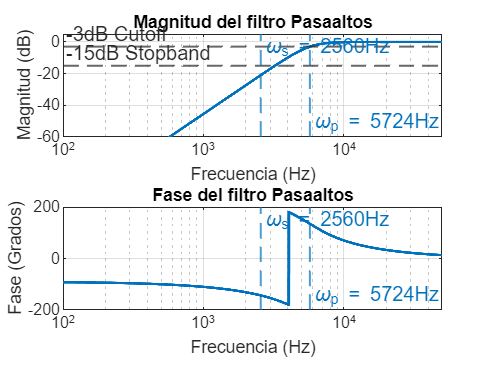

figure(4)
subplot(2,1,1);
semilogx(w_range/(2*pi), 20*log10(abs(h4)), 'LineWidth', 1.5);
grid on;
title('Magnitud del filtro Pasaaltos');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud (dB)');

ylim([-60 5]); % Limitar eje Y para ver bien la banda de paso
yline(-3, '--', label_3, 'LineWidth',1,'LabelOrientation','horizontal','LabelHorizontalAlignment','left','HandleVisibility','off'); % Línea de referencia
yline(-15, '--',label_15, 'LineWidth',1,'LabelOrientation','horizontal','LabelHorizontalAlignment','left','HandleVisibility','off'); % Línea de referencia
%xline(fc_1_2, 'Color', [0 0.4470 0.7410], 'LineWidth', 1,'HandleVisibility', 'off');
label11 = sprintf("\\omega_p = %.0f{Hz}", fc_3_4);
label12 = sprintf("\\omega_s = %.0f{Hz}", f0(3));
xline(fc_3_4, '--', label11, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(f0(3), '--', label12, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xlim([100 50000]);

subplot(2, 1, 2);
semilogx(w_range/(2*pi), rad2deg(angle(h4)), 'LineWidth', 1.5);
grid on;
title('Fase del filtro Pasaaltos');
xlabel('Frecuencia (Hz)');
ylabel('Fase (Grados)');
xline(fc_3_4, '--', label11, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(f0(3), '--', label12, 'Color',[0 0.4470 0.7410],'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','top', 'HandleVisibility','off');
xlim([100 50000]);

**Gráficas Completas**

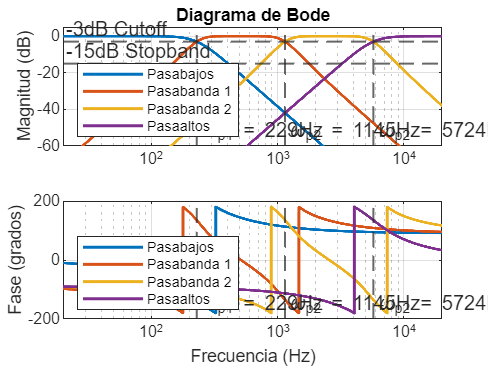

%Gráfica de Magnitud
subplot(2, 1, 1); 
semilogx(w_range/(2*pi), 20*log10(abs(h1)), 'LineWidth', 1.5); 
hold on
yline(-3, '--', label_3, 'LineWidth',1,'LabelOrientation','horizontal','LabelHorizontalAlignment','left','HandleVisibility','off'); % Línea de referencia
yline(-15, '--',label_15, 'LineWidth',1,'LabelOrientation','horizontal','LabelHorizontalAlignment','left','HandleVisibility','off'); % Línea de referencia
semilogx(w_range/(2*pi), 20*log10(abs(h2)), 'LineWidth', 1.5);
semilogx(w_range/(2*pi), 20*log10(abs(h3)), 'LineWidth', 1.5);
semilogx(w_range/(2*pi), 20*log10(abs(h4)), 'LineWidth', 1.5);
xline(fc_1_2, '--', label3,'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(fc_2_3, '--', label4,'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(fc_3_4, '--', label8,'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');

grid on;
ylabel('Magnitud (dB)');
title('Diagrama de Bode');
legend("Pasabajos", "Pasabanda 1", "Pasabanda 2", "Pasaaltos","Location","southwest");
xlim([20 20000]);
ylim([-60 5]);

%Gráfica de Fase
subplot(2, 1, 2);
semilogx(w_range/(2*pi), rad2deg(angle(h1)), 'LineWidth', 1.5);
hold on
semilogx(w_range/(2*pi), rad2deg(angle(h2)), 'LineWidth', 1.5);
semilogx(w_range/(2*pi), rad2deg(angle(h3)), 'LineWidth', 1.5);
semilogx(w_range/(2*pi), rad2deg(angle(h4)), 'LineWidth', 1.5);
xline(fc_1_2, '--', label3,'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(fc_2_3, '--', label4,'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');
xline(fc_3_4, '--', label8,'LineWidth',1,'LabelOrientation','horizontal', 'LabelVerticalAlignment','bottom','HandleVisibility','off');

grid on;
xlabel('Frecuencia (Hz)');
ylabel('Fase (grados)');
legend("Pasabajos", "Pasabanda 1", "Pasabanda 2", "Pasaaltos","Location","southwest");
xlim([20 20000]);